# BME3053C Project

Part I - Using test images to decide on thresholding values. Note: Each image is 512x512 pixels and is color normalized. Thresholding values between >0 and >50 were tested. Results from this part of the code can be found in the 'Thresholding Tests' spreadsheet. Patients 1-20 were used to test thresholds. 

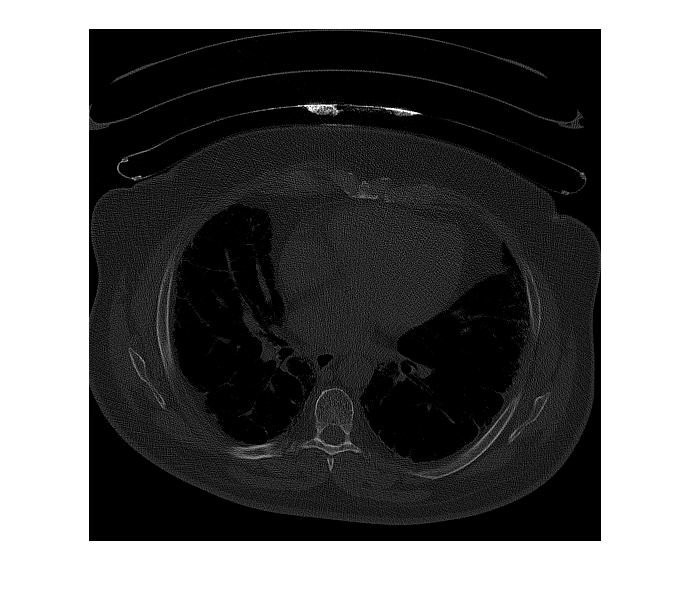

clc, clear
img = imread('Patient 20.png'); %read an image that corresponds to the CT of a patient
imshow(img) %Display CT imsage

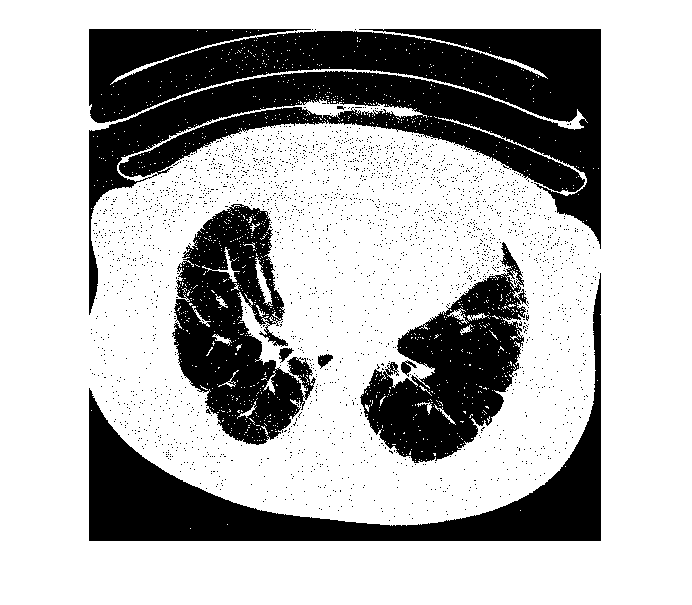

img = im2gray(img); %Ensure that input image is in grayscale format
binary0 = img>0; % Lines 5-15: Creating different binary images with different thresholding values
binary5 = img>5;
binary10 = img>10;
binary15 = img>15;
binary20 = img>20;
binary25 = img>25;
binary30 = img>30;
binary35 = img>35;
binary40 = img>40;
binary45 = img>45;
binary50 = img>50;
imshow(binary0) % Lines 16-26: Display resulting binary images

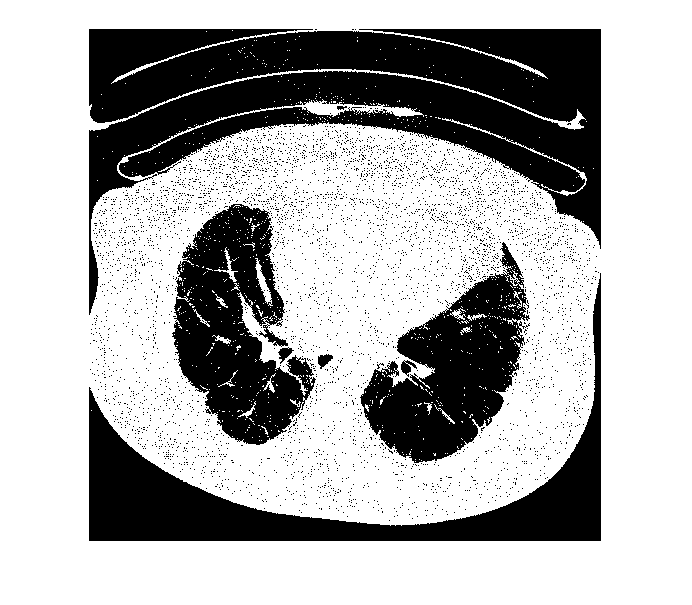

imshow(binary5) 

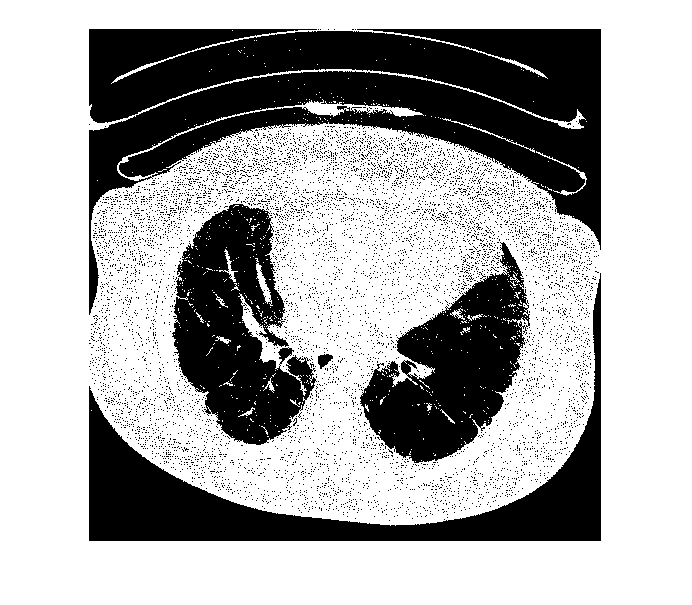

imshow(binary10)

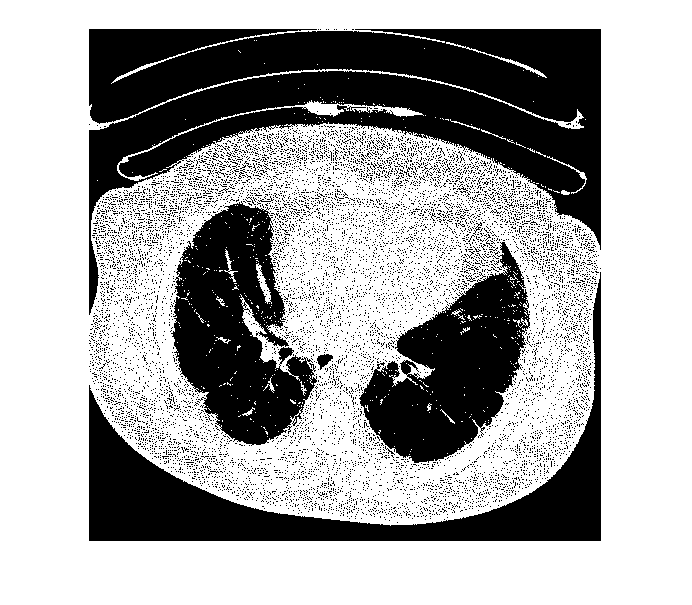

imshow(binary15)

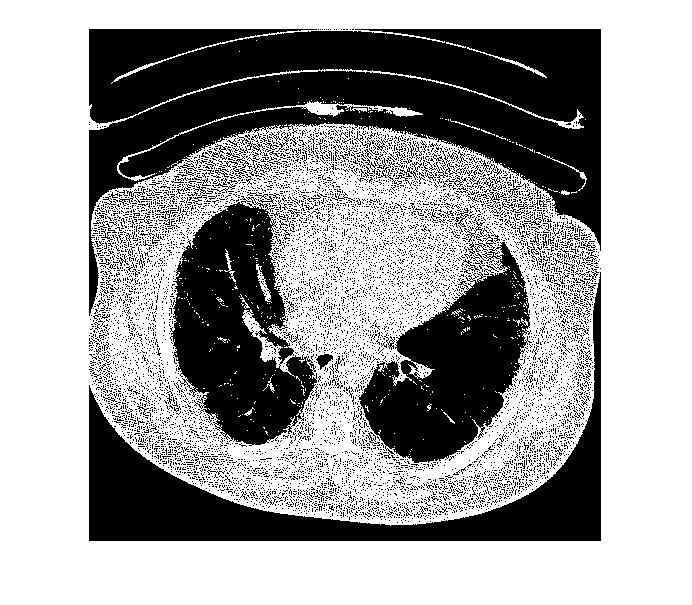

imshow(binary20)

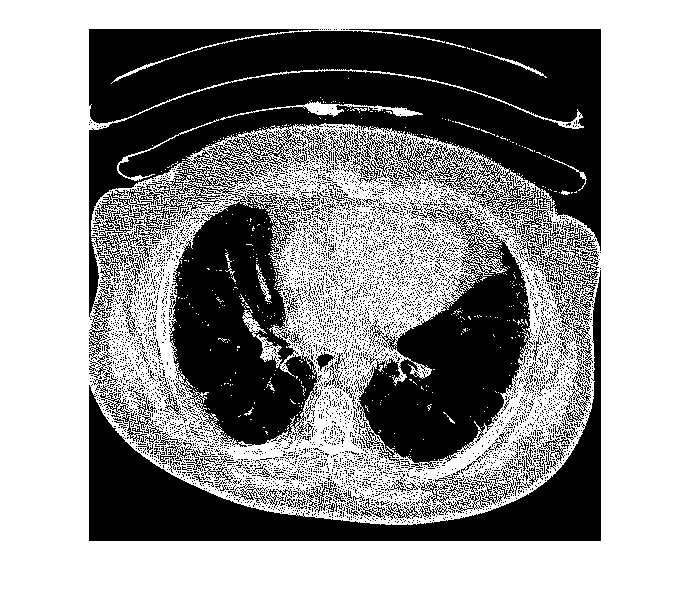

imshow(binary25)

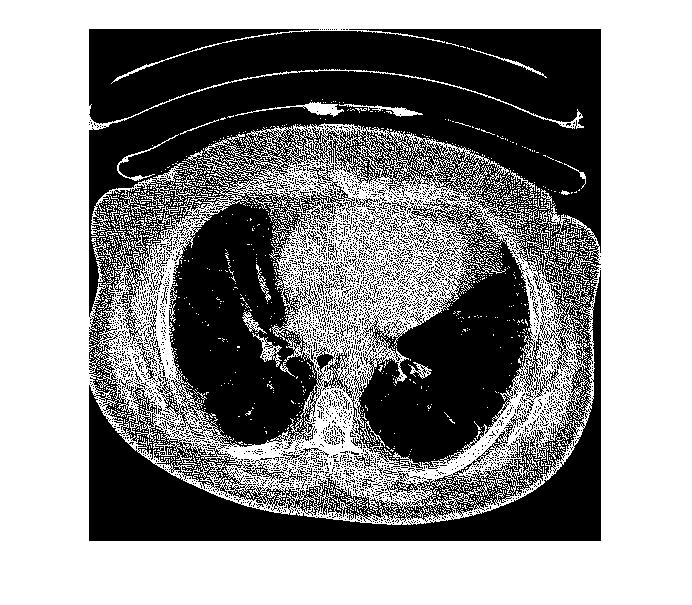

imshow(binary30)

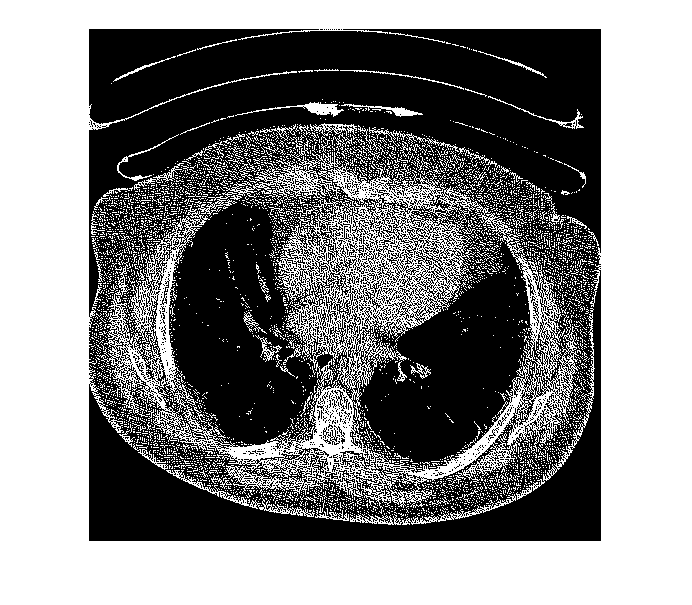

imshow(binary35)

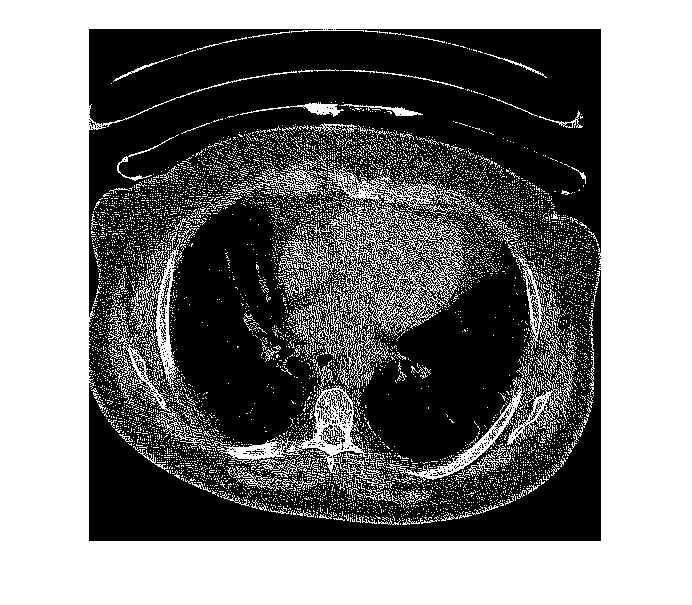

imshow(binary40)

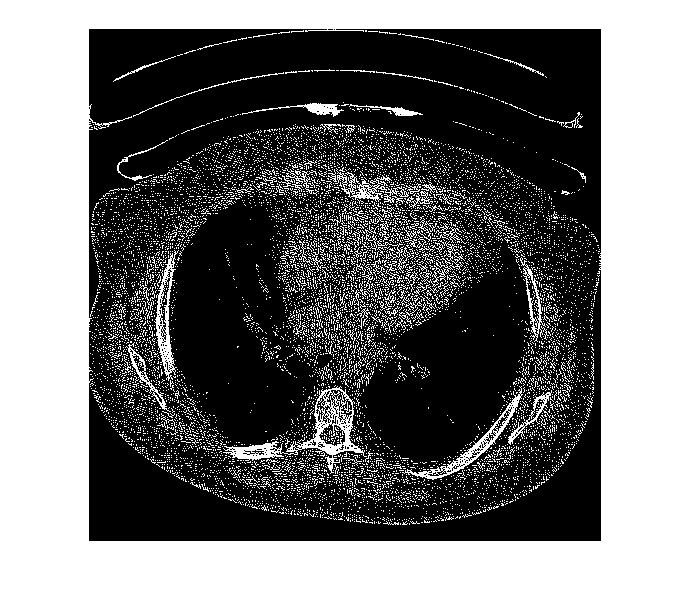

imshow(binary45)

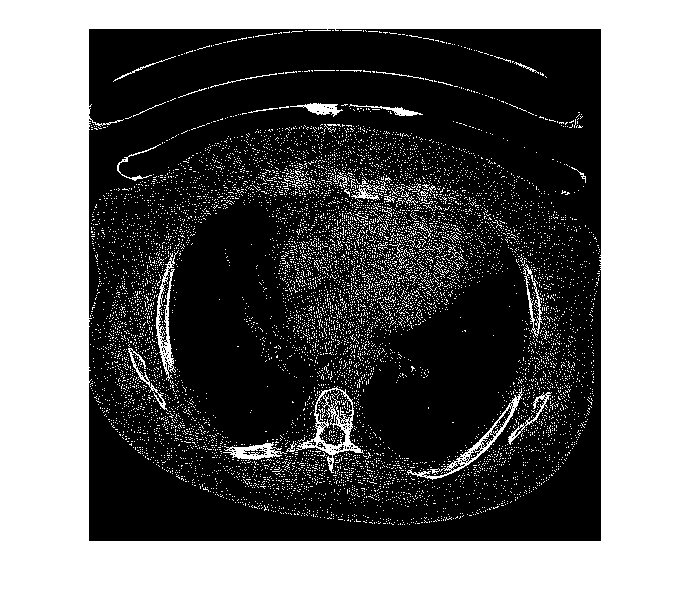

imshow(binary50)

WhiteCount0 = 0; % Lines 27-37: Set a counter for each binary image that will keep track of the number of true or "white" pixels in each image
WhiteCount5 = 0;
WhiteCount10 = 0;
WhiteCount15 = 0;
WhiteCount20 = 0;
WhiteCount25 = 0;
WhiteCount30 = 0;
WhiteCount35 = 0;
WhiteCount40 = 0;
WhiteCount45 = 0;
WhiteCount50 = 0;

[a, b] = size(binary0); % Set variables corresponding to the dimensions of the binary image
for ii = 1:a % This for loop runs through every row of the image
    for jj = 1:b % This for loop runs through every column of the image
        if binary0(ii,jj) == 1 % This logical determines whether the pixel at a given index is true on the binary image
            WhiteCount0 = WhiteCount0+1; % If the indexed pixel is true on the binary image, the counter for the corresponding binary image increases by 1. 
            % This process is repeated for every pixel
        end
    end
end
% Lines 49-56: Every pixel in the binary image for thresholding of >5 is checked and counted
[a, b] = size(binary5);
for ii = 1:a
    for jj = 1:b
        if binary5(ii,jj) == 1
            WhiteCount5 = WhiteCount5+1;
        end
    end
end
% Lines 58-65: Every pixel in the binary image for thresholding of >10 is checked and counted
[a, b] = size(binary10);
for ii = 1:a
    for jj = 1:b
        if binary10(ii,jj) == 1
            WhiteCount10 = WhiteCount10+1;
        end
    end
end
% Lines 66-74: Every pixel in the binary image for thresholding of >15 is checked and counted
[a, b] = size(binary15);
for ii = 1:a
    for jj = 1:b
        if binary15(ii,jj) == 1
            WhiteCount15 = WhiteCount15+1;
        end
    end
end
% Lines 76-83: Every pixel in the binary image for thresholding of >20 is checked and counted
[a, b] = size(binary20);
for ii = 1:a
    for jj = 1:b
        if binary20(ii,jj) == 1
            WhiteCount20 = WhiteCount20+1;
        end
    end
end
% Lines 83-92: Every pixel in the binary image for thresholding of >25 is checked and counted
[a, b] = size(binary25);
for ii = 1:a
    for jj = 1:b
        if binary25(ii,jj) == 1
            WhiteCount25 = WhiteCount25+1;
        end
    end
end
% Lines 94-101: Every pixel in the binary image for thresholding of >30 is checked and counted
[a, b] = size(binary30);
for ii = 1:a
    for jj = 1:b
        if binary30(ii,jj) == 1
            WhiteCount30 = WhiteCount30+1;
        end
    end
end
% Lines 103-110: Every pixel in the binary image for thresholding of >35 is checked and counted
[a, b] = size(binary35);
for ii = 1:a
    for jj = 1:b
        if binary35(ii,jj) == 1
            WhiteCount35 = WhiteCount35+1;
        end
    end
end
% Lines 112-119: Every pixel in the binary image for thresholding of >40 is checked and counted
[a, b] = size(binary40);
for ii = 1:a
    for jj = 1:b
        if binary40(ii,jj) == 1
            WhiteCount40 = WhiteCount40+1;
        end
    end
end
% Lines 121-128: Every pixel in the binary image for thresholding of >45 is checked and counted
[a, b] = size(binary45);
for ii = 1:a
    for jj = 1:b
        if binary45(ii,jj) == 1
            WhiteCount45 = WhiteCount45+1;
        end
    end
end
% Lines 130-137: Every pixel in the binary image for thresholding of >50 is checked and counted
[a, b] = size(binary50);
for ii = 1:a
    for jj = 1:b
        if binary50(ii,jj) == 1
            WhiteCount50 = WhiteCount50+1;
        end
    end
end
Counts = [WhiteCount0 WhiteCount5 WhiteCount10 WhiteCount15 WhiteCount20 WhiteCount25 WhiteCount30 WhiteCount35 WhiteCount40 WhiteCount45 WhiteCount50] % Creating a horizontal vector for ease of transferring results to spreadsheet

Counts =       137487      132523      126155      117494      106319       92374       76459       60476       45501       32550       22565
